clear
load("chips20.mat")
load("illum.mat")
load("xyz.mat")
%e = R .* I
eD65=ones(1,61).*CIED65;
% Raw
d=(xyz'*(chips20.*CIED65)')'

d =    14.3149   14.4780   13.1313
    6.2723    5.5867    6.1112
    2.2246    2.2511    3.1156
    3.6794    3.6194    4.5058
    8.0181   10.6112   10.8246
    6.7734    7.6038    8.7172
   11.1639   12.3079    2.1528
    1.5393    1.3867    1.3832
    7.6876    8.2380    1.1754
    0.9837    0.9768    0.9489


% Apply normalization (d' = d.*e)
cal=xyz'.*eD65

cal =     0.0092    0.0169    0.0354    0.0701    0.1333    0.2286    0.3226    0.3884    0.4279    0.4320    0.4215    0.3981    0.3619    0.3134    0.2446    0.1779    0.1198    0.0717    0.0391    0.0173    0.0056    0.0026    0.0096    0.0293    0.0620    0.1080    0.1640    0.2283    0.2998    0.3770    0.4610    0.5450    0.6329    0.7120    0.7883    0.8523    0.9061    0.9449    0.9671    0.9770    0.9633    0.9414    0.8961    0.8373    0.7611    0.6689    0.5716    0.4816    0.3976    0.3210
    0.0003    0.0004    0.0010    0.0020    0.0040    0.0078    0.0132    0.0199    0.0283    0.0370    0.0476    0.0600    0.0747    0.0922    0.1139    0.1410    0.1741    0.2092    0.2538    0.3043    0.3661    0.4415    0.5203    0.6125    0.6956    0.7815    0.8541    0.9255    0.9848    1.0273    1.0583    1.0642    1.0593    1.0270    0.9847    0.9260    0.8603    0.7882    0.7133    0.6425    0.5723    0.5103    0.4496    0.3937    0.3394    0.2858    0.2358    0.1929    0.1553   

dCal=d*cal

dCal =     0.7054    1.3006    2.7410    5.4369   10.3743   17.9047   25.4867   31.0485   34.7168   35.7711   35.8978   35.1762   33.5431   30.8676   26.3140   21.7207   17.6091   14.0613   11.6889   10.1139    9.4280    9.4503    9.8188   10.7640   11.9648   13.6022   15.2623   17.0634   18.8247   20.4542   22.0429   23.2873   24.4520   25.0984   25.5685   25.6303   25.4473   24.9554   24.1851   23.3057   22.0849   20.8717   19.3401   17.6877   15.8102   13.7142   11.5956    9.6862    7.9409    6.3756
    0.3244    0.5982    1.2607    2.5007    4.7716    8.2347   11.7204   14.2755   15.9576   16.4366   16.4874   16.1465   15.3836   14.1372   12.0199    9.8770    7.9480    6.2752    5.1325    4.3498    3.9641    3.8889    3.9669    4.2929    4.7434    5.3885    6.0558    6.7867    7.5103    8.1896    8.8606    9.4003    9.9135   10.2208   10.4586   10.5300   10.4995   10.3384   10.0575    9.7258    9.2439    8.7591    8.1339    7.4522    6.6707    5.7928    4.9023    4.0982    3.3618  

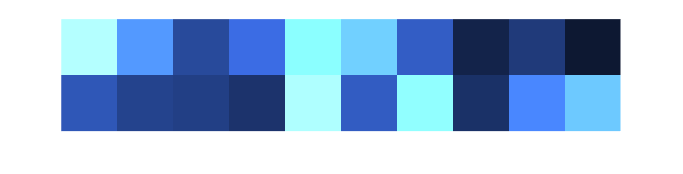



showRGB(dCal)